正在生成《妈妈的吻》 (单簧管风格 + 指数包络)...


音符总数: 142


生成完毕！文件已保存为: Mom Kiss.wav


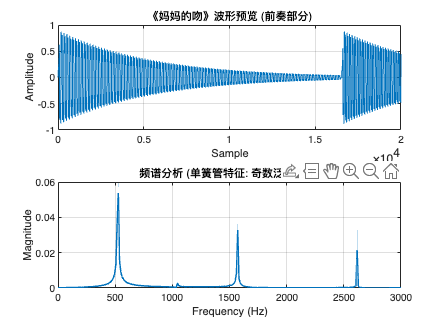

clear; clc;

fs = 44100;          
scale = 'F';         
bpm = 80;            
one_beat = 60/bpm;   

% 音色设置：单簧管风格
timbre_weights = [1.0, 0.05, 0.5, 0.0, 0.3, 0.0, 0.1];

% --- 前奏 ---
T_intro = [5 6 1 6 5 3, 6 1 2 3 2 1 6 5, 1 2 3 2 1 2];
O_intro = [-1 -1 0 -1 -1 -1, -1 0 0 0 0 0 -1 -1, 0 0 0 0 0 0];
R_intro = zeros(size(T_intro));
B_intro = [0.5 0.5 0.5 0.5 1 1, 0.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5, 1.5 0.5 0.5 0.5 0.5 2];

% --- 主歌 A段 ---
T_v1 = [1 1 2, 3 3 2 1 1 6 5, 1 2 3 2 1 2];
O_v1 = [0 0 0, 0 0 0 0 0 -1 -1, 0 0 0 0 0 0];
R_v1 = zeros(size(T_v1));
B_v1 = [1 0.5 0.5, 1 0.5 0.5 0.5 0.5 0.5 0.5, 1.5 0.5 0.5 0.5 0.5 2];

T_v2 = [1 1 2 3 3 2 2 2 1, 6 6 2 1 1 6, 5];
O_v2 = [0 0 0 0 0 0 0 0 0, -1 -1 0 0 0 -1, -1];
R_v2 = zeros(size(T_v2));
B_v2 = [1 0.5 0.5 1 0.5 0.5 0.5 0.5 0.5, 1.5 0.5 1.5 0.5 0.5 0.5, 3];

% --- 主歌 B段 ---
T_v3 = [5 5 6 1 1, 2 3 2 1 6, 2 3 2 1 1 2 6 5 6];
O_v3 = [-1 -1 -1 0 0, 0 0 0 0 -1, 0 0 0 0 0 0 -1 -1 -1];
R_v3 = zeros(size(T_v3));
B_v3 = [0.5 0.5 0.5 1 1, 0.5 0.5 0.5 0.5 2, 1.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5 1];

T_v4 = [5 6 1 2 3, 5 3 2 1 2 1 6, 6 2 7 6 5, 5];
O_v4 = [-1 -1 0 0 0, 0 0 0 0 0 0 -1, -1 0 -1 -1 -1, -1];
R_v4 = zeros(size(T_v4));
B_v4 = [1.5 0.5 1 1 1, 1 0.5 0.5 0.5 0.5 0.5 0.5, 1 1 1 0.5 0.5, 3];

% --- 副歌 ---
T_ch1 = [5 5 5 5 5 3 5 6, 6 5 3, 6 6 5 6 6 5 5 3, 2];
O_ch1 = [0 0 0 0 0 0 0 0, 0 0 0, 0 0 0 0 0 0 0 0, 0];
R_ch1 = zeros(size(T_ch1));
B_ch1 = [0.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5, 1.5 0.5 2, 0.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5, 3];

T_ch2 = [6 5 6 2, 2 3 2 1 6, 2 2 2 2 1 6, 5];
O_ch2 = [-1 -1 -1 0, 0 0 0 0 -1, 0 0 0 0 0 -1, -1];
R_ch2 = zeros(size(T_ch2));
B_ch2 = [1 0.5 0.5 2, 0.5 0.5 0.5 0.5 2, 1.5 0.5 0.5 0.5 0.5 0.5, 3];

% --- 结尾 ---
T_end = [5 5 6 3, 2 3 2 1 6, 3 2 2 2 1 6, 5 0];
O_end = [-1 -1 -1 0, 0 0 0 0 -1, 0 0 0 0 0 -1, -1 0];
R_end = zeros(size(T_end));
B_end = [1 0.5 0.5 2, 0.5 0.5 0.5 0.5 2, 1.5 0.5 0.5 0.5 1 1, 3 1];

% --- 数据拼接 ---
Tones    = [T_intro T_v1 T_v2 T_v3 T_v4 T_ch1 T_ch2 T_end];
Octaves  = [O_intro O_v1 O_v2 O_v3 O_v4 O_ch1 O_ch2 O_end];
Risings  = [R_intro R_v1 R_v2 R_v3 R_v4 R_ch1 R_ch2 R_end];
Beats    = [B_intro B_v1 B_v2 B_v3 B_v4 B_ch1 B_ch2 B_end];

%% 2. 核心调用

fprintf('正在生成《妈妈的吻》音频...\n');
music_wave = gen_music_poly(Tones, scale, Octaves, Risings, Beats, one_beat, fs, timbre_weights);

%% 3. 保存与绘图

filename = 'Mom Kiss.wav';
audiowrite(filename, music_wave, fs);
fprintf('文件已保存: %s\n', filename);

figure('Color', 'w');
subplot(2,1,1);
plot(music_wave(1:min(length(music_wave), 20000))); 
title('波形预览'); xlabel('Sample'); ylabel('Amp'); grid on;

subplot(2,1,2);
L = 4096; snippet = music_wave(floor(end/2):floor(end/2)+L-1);
f_axis = fs*(0:(L/2))/L; P1 = abs(fft(snippet)/L); P1 = P1(1:L/2+1);
plot(f_axis, P1, 'LineWidth', 1.5); xlim([0 3000]);
title('频谱预览'); xlabel('Freq (Hz)'); ylabel('Mag'); grid on;

%% 4. 函数定义

function full_music = gen_music_poly(tones, scale, noctaves, risings, beats, one_beat, fs, weights)
    full_music = [];
    
    for i = 1:length(tones)
        duration = beats(i) * one_beat;
        wav = gen_wave_poly(tones(i), scale, noctaves(i), risings(i), duration, fs, weights);
        full_music = [full_music, wav];
    end
    
    full_music = full_music / max(abs(full_music)) * 0.9;
end

function waves = gen_wave_poly(tone, scale, noctave, rising, duration, fs, weights)
    t = linspace(0, duration, round(duration * fs));
    
    if tone == 0
        waves = zeros(1, length(t));
        return;
    end
    
    f0 = tone2freq2(tone, scale, noctave, rising);
    
    waves = zeros(1, length(t));
    for k = 1:length(weights)
        amp = weights(k);
        if amp > 0
            waves = waves + amp * sin(2 * pi * (k * f0) * t);
        end
    end
    
    decay = exp(-3 * t / duration); 
    
    fade_len = min(100, floor(length(t)/10));
    env = ones(1, length(t));
    env(1:fade_len) = linspace(0, 1, fade_len);
    env(end-fade_len+1:end) = linspace(1, 0, fade_len);
    
    waves = waves .* decay .* env;
end

function freq = tone2freq2(tone, scale, noctave, rising)
    switch scale
        case 'F', base = 349.23;
        case 'C', base = 261.63;
        case 'D', base = 293.66;
        case 'E', base = 329.63;
        case 'G', base = 392.00;
        case 'A', base = 440.00;
        case 'B', base = 493.88;
        otherwise, base = 261.63;
    end
    dic = [0, 2, 4, 5, 7, 9, 11];
    if tone >= 1 && tone <= 7
        n = dic(tone) + noctave * 12 + rising;
        freq = base * (2 ^ (n / 12));
    else
        freq = 0;
    end
end